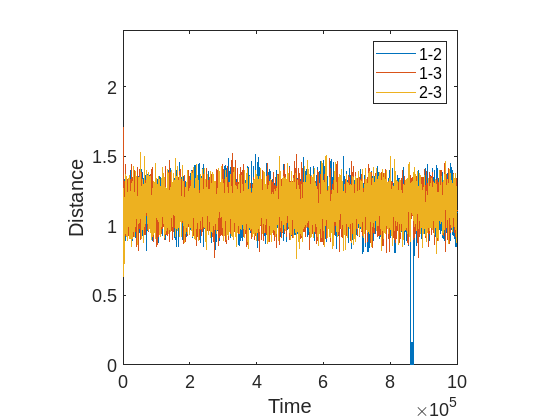

addpath('/nas/longleaf/home/acoletti/paper_figures/3-bead');

load('systems.mat');

%amorphic/unbound/"large triangle"

param = 0.001; 
system2.a = @(x)param*2./(1+exp(20*(abs(x)-0.75)));
system2.param = param; 
x = [0 -1 0 -1 0 1];
x = find_minima(system2, x); %starting configuration
xout = simulate_system_param(system2, x, 1e-3, 1000000,0.01);

% Create plot of bead-bead distance
plotbeaddist(xout)
axis square
set(gca, "FontSize", 14);

%saveas(gcf, "figure2a_1.png")

 

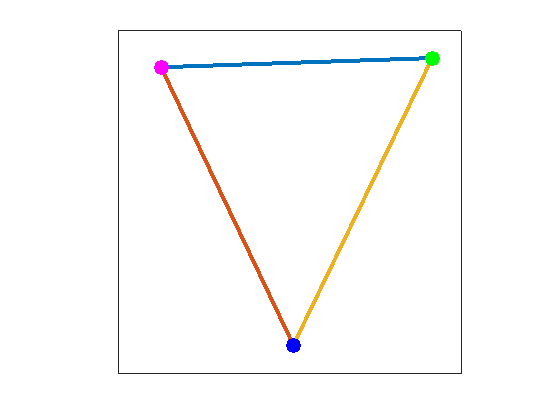

%plot2dbeads(xout(:,:,1800))

x = [-0.4511 0.4975 0.0117; 0.4733 0.5054 -0.4986];
plot2dbeads(x)

xlim([-0.6 0.6])
ylim([-0.6 0.6])
box on
set(gca,'xtick',[])
set(gca,'ytick',[])
pbaspect([1 1 1])


%saveas(gcf, "figures2a_2png")

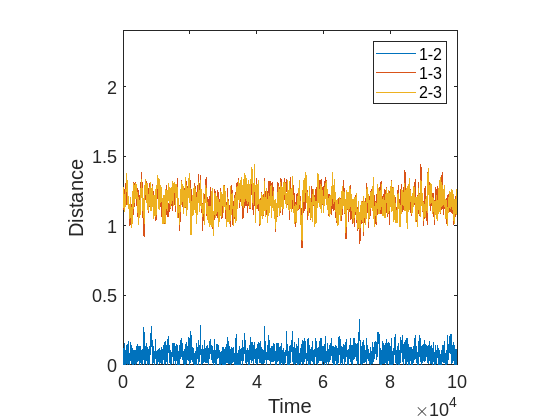

%2-bead cluster 
param = 10; 
system2.a = @(x)param*2./(1+exp(20*(abs(x)-0.75)));
system2.param = param; 
x = [0 -1 0 -1 0 1];
x = find_minima(system2, x); %starting configuration 2-bead cluster
xout = simulate_system_param(system2, x, 1e-3, 100000,0.01);

% Create plot of bead-bead distance
plotbeaddist(xout)
axis square
set(gca, "FontSize", 14);

%saveas(gcf, "figure2b_1.png")

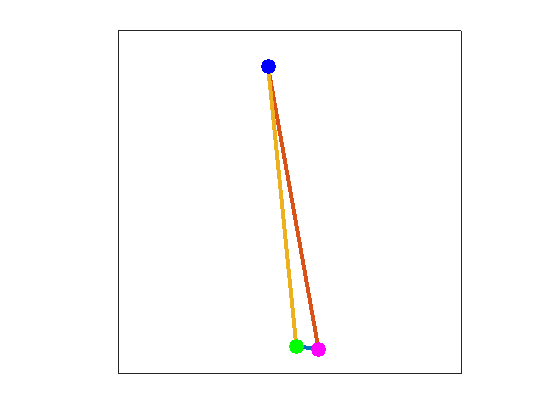

%plot2dbeads(xout(:,:,320))

x = [0.1001 0.0223 -0.0768; -0.5056 -0.4946 0.5659];
plot2dbeads(x)

xlim([-0.6 0.6])
ylim([-0.6 0.7])
box on
set(gca,'xtick',[])
set(gca,'ytick',[])
pbaspect([1 1 1])



%saveas(gcf, "figures2b_2png")

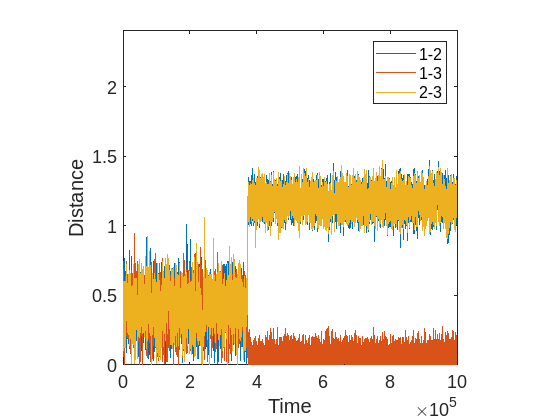

%3-bead cluster/"small triangle"
param = 5; 
system2.a = @(x)param*2./(1+exp(20*(abs(x)-0.75)));
system2.param = param; 

x = [-0.1779 -0.1027 0.1779 -0.1027 0 0.2055]; 
x = find_minima(system2, x); %starting configuration triagle
xout = simulate_system_param(system2, x, 1e-3, 1000000,0.01);

% Create plot of bead-bead distance
plotbeaddist(xout)
axis square
set(gca, "FontSize", 14);

%saveas(gcf, "figure2c_1.png")

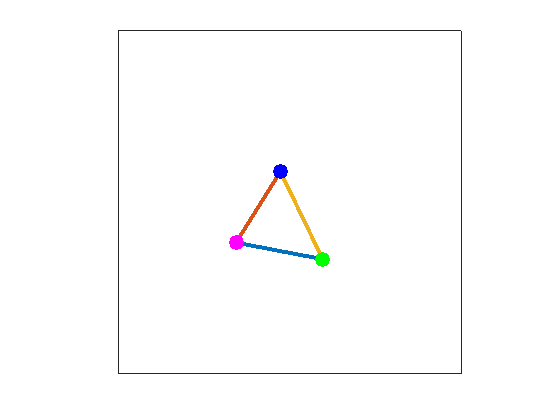

%plot2dbeads(xout(:,:,320)) %plot from the simulated data

x = [-0.1887 0.1144 -0.0334; -0.1020 -0.1647 0.1670];
plot2dbeads(x)

xlim([-0.6 0.6])
ylim([-0.6 0.7])
box on
set(gca,'xtick',[])
set(gca,'ytick',[])
pbaspect([1 1 1])


%saveas(gcf, "figures2c_2png")

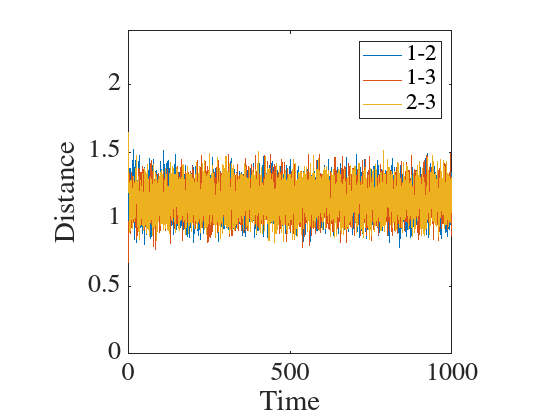

%plot the pairwise distance plots from saved data

%all beads unbound
load("Figure2_xout_data/allunbound_xout.mat", "xout")
plotbeaddist(xout, 0.001) 
set(gca, "FontSize", 20, "FontName", "Times");
axis square


%two bead cluster 
load("Figure2_xout_data/twobeadcluster_xout.mat", "xout")
plotbeaddist(xout, 0.001) 
set(gca, "FontSize", 20, "FontName", "Times");
axis square


%triangle 
load("Figure2_xout_data/triangle_xout.mat", "xout")
plotbeaddist(xout, 0.001) 
set(gca, "FontSize", 20, "FontName", "Times");
axis square
